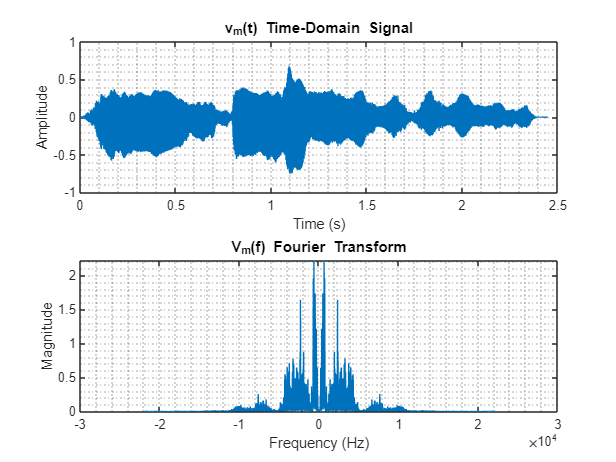

%1.1

[v_m,fs] = audioread('in-the-air.wav');
%sound(v_m,fs);
v_m=v_m(:,1);

Ts=1/fs;
N=length(v_m);
t = 0:Ts:(N-1)*Ts;
f = linspace(-fs/2,fs/2,N);
V_m = fftshift(fft(v_m)) / sqrt(N);

%1.1.1
% Plot time-domain signal
subplot(2, 1, 1);
plot(t, v_m');
hold on
grid minor
xlabel('Time (s)');
ylabel('Amplitude');
title('v_m(t) Time-Domain Signal');
hold off
%  Fourier transform plot
subplot(2, 1, 2);
plot(f, abs(V_m));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('V_m(f) Fourier Transform');
grid minor
hold off

clf 

%1.1.2

%Band width evaluation 
psd = (1/N)*abs(V_m).^2;
cdf = cumsum(psd)/sum(psd);
%no error pick
threshold = 1;
idx = find(cdf >= threshold, 1);
bandwidth = f(idx);
fprintf('Bandwidth of signal: %0.2f Hz\n', bandwidth);

Bandwidth of signal: 22050.00 Hz


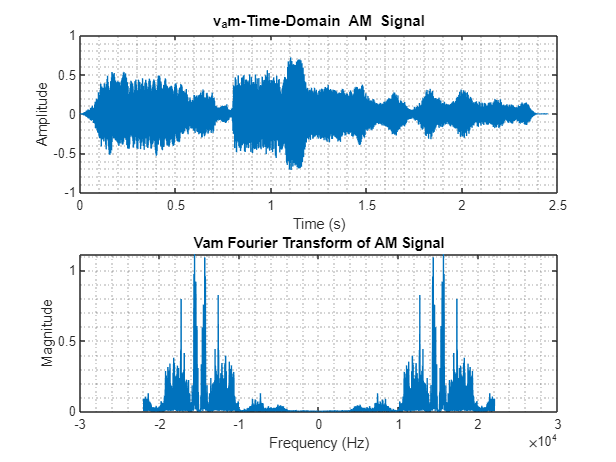


%1.2.1
fc=15*10^3;
kam=0.02;
v_am=ammod(v_m,fc,fs);
% Plot AM time-domain signal

subplot(2, 1, 1);
plot(t, v_am');
hold on
grid minor
xlabel('Time (s)');
ylabel('Amplitude');
title('v_am-Time-Domain AM Signal');
hold off 
%  Fourier transform plot
V_am=fftshift(fft(v_am)) / sqrt(N);
subplot(2, 1, 2);
plot(f, abs(V_am));
grid minor
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Vam Fourier Transform of AM Signal');
hold off

clf

%1.2.3
sound(v_am,fs);
%explain why im hearing everything in such a distortion 

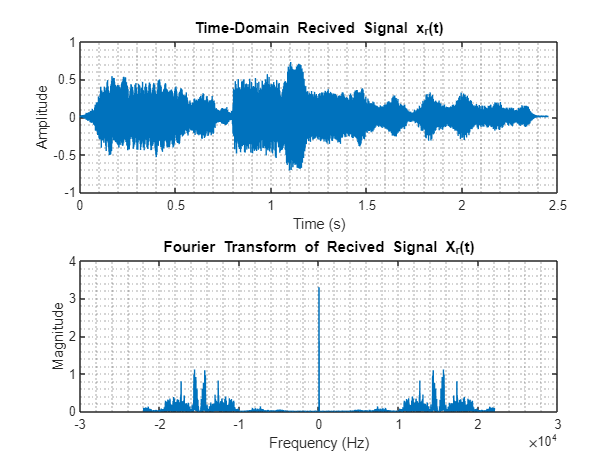


%1.3.1
z=0.02*rand(1,N)';
%1.3.2 
%Generate recived signal with noise
xrt=v_am+z;
subplot(2,1,1)
plot(t,xrt)
hold on
xlabel('Time (s)');
ylabel('Amplitude');
title('Time-Domain Recived Signal x_r(t)');
grid minor
hold off 
Xrt=fftshift(fft(xrt)) / sqrt(N);
subplot(2,1,2)
plot(f,abs(Xrt))
hold on 
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Fourier Transform of Recived Signal X_r(t)');
grid minor
hold off

clf
%explaination 



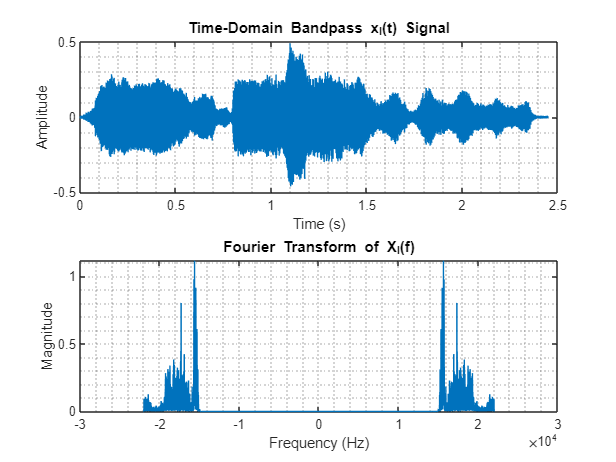


%1.4.1
%first we need to determind the range of the bandpass frequency propertly 
%we can see from the graph 

xl=bandpass(xrt,[15000,22000],fs);
subplot(2,1,1)
plot(t,xl)
hold on 
xlabel('Time (s)');
ylabel('Amplitude');
title('Time-Domain Bandpass x_l(t) Signal');
grid minor
hold off
XL=fftshift(fft(xl)) / sqrt(N);
subplot(2,1,2)
plot(f,abs(XL))
hold on 
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Fourier Transform of X_l(f)');
grid minor
hold off

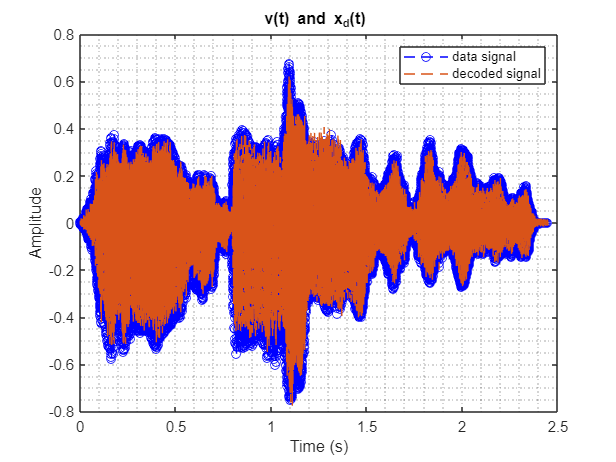

clf

%1.4.2
x_d=amdemod(xl,fc,fs);
plot(t, v_m, 'b--o');
hold on;
plot(t, x_d,'--');
xlabel('Time (s)');
ylabel('Amplitude');
title('v(t) and x_d(t) ');
legend('data signal', 'decoded signal');
grid minor
hold off

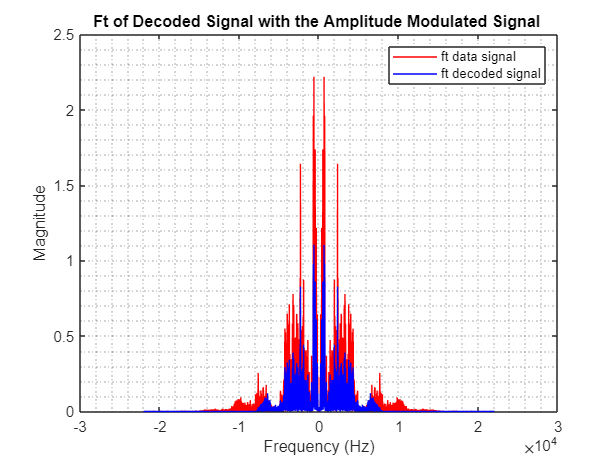

clf
%lowpass for x_d 
x_d=lowpass(x_d,6000,fs);
%explaination 
X_d=fftshift(fft(x_d)) / sqrt(N);
sound(x_d,fs)
plot(f, abs(V_m),'r');
hold on;
plot(f, abs(X_d), 'b');

xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Ft of Decoded Signal with the Amplitude Modulated Signal ');
grid minor
legend('ft data signal', 'ft decoded signal');
hold off

clf



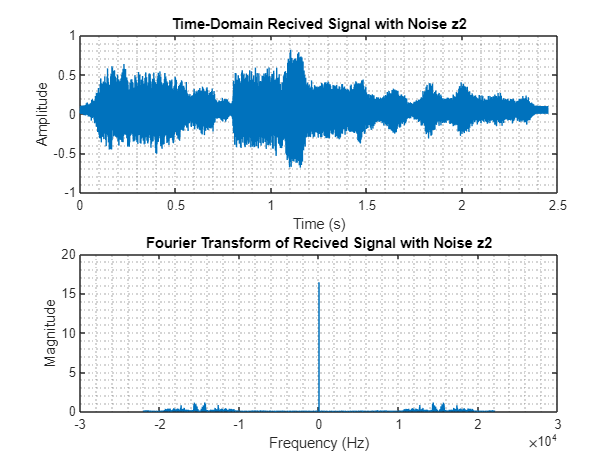

%1.5
%1.5.1 - 1.3.1 
z2=0.1*rand(1,N)';
%1.5 - 1.3.2 
%Generate recived signal with noise
xrt2=v_am+z2;
subplot(2,1,1)
plot(t,xrt2)
hold on
xlabel('Time (s)');
ylabel('Amplitude');
title('Time-Domain Recived Signal with Noise z2');
grid minor
hold off 

%[b,a] = iirnotch(0.1/(fs/2), 0.1);
%Xrt2=fft(filter(b,a,xrt2))
Xrt2=fftshift(fft(xrt2)) / sqrt(N);
subplot(2,1,2)
plot(f,abs(Xrt2))
hold on 
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Fourier Transform of Recived Signal with Noise z2');
grid minor
hold off

clf
%explaination 



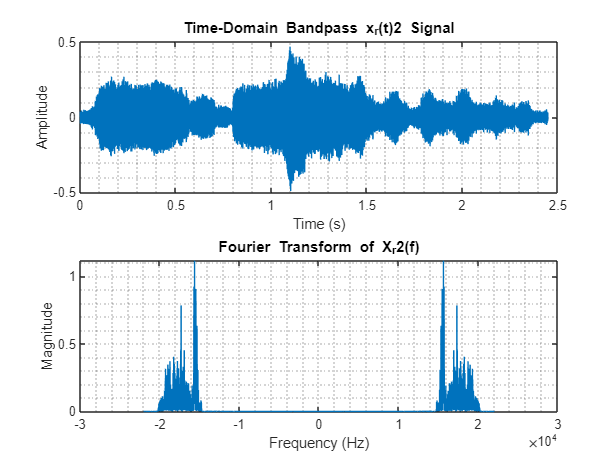


%1.5.1-1.4.1
%first we need to determind the range of the bandpass frequency propertly 
%we can see from the graph 

xl2=bandpass(xrt2,[15000,20000],fs);
subplot(2,1,1)
plot(t,xl2)
hold on 
xlabel('Time (s)');
ylabel('Amplitude');
title('Time-Domain Bandpass x_r(t)2 Signal');
grid minor
hold off
XL2=fftshift(fft(xl2)) / sqrt(N);
subplot(2,1,2)
plot(f,abs(XL2))
hold on 
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Fourier Transform of X_r2(f)');
grid minor
hold off

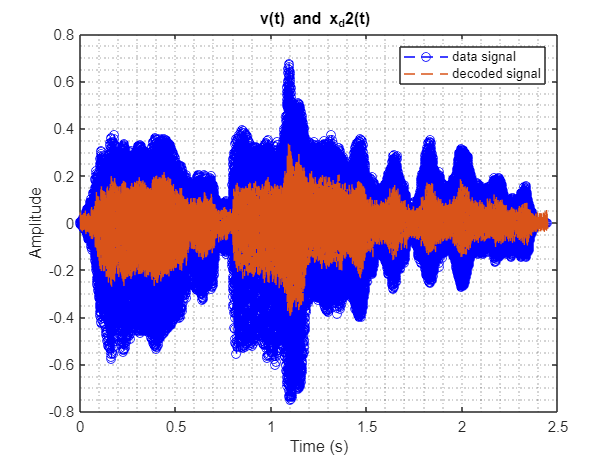

clf

%1.5.1-1.4.2
x_d2=amdemod(xl2,fc,fs);
x_d2=lowpass(x_d2,5000,fs);
plot(t, v_m, 'b--o');
hold on;
plot(t, x_d2,'--');
xlabel('Time (s)');
ylabel('Amplitude');
title('v(t) and x_d2(t) ');
legend('data signal', 'decoded signal');
grid minor
hold off

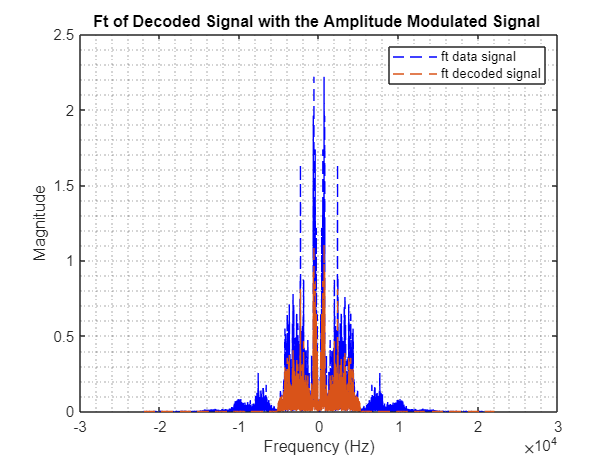

clf
%explaination 
sound(x_d2,fs)
X_d2=fftshift(fft(x_d2)) / sqrt(N);
plot(f, abs(V_m), 'b--');
hold on;
plot(f, abs(X_d2),'--');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Ft of Decoded Signal with the Amplitude Modulated Signal ');
grid minor
legend('ft data signal', 'ft decoded signal');
hold off

clf
%sound(x_d2)
correlation_factor1=xcorr(x_d,v_m,0,'coeff')

correlation_factor1 = 0.9883

correlation_factor2=xcorr(x_d2,v_m,0,'coeff')

correlation_factor2 = 0.9678